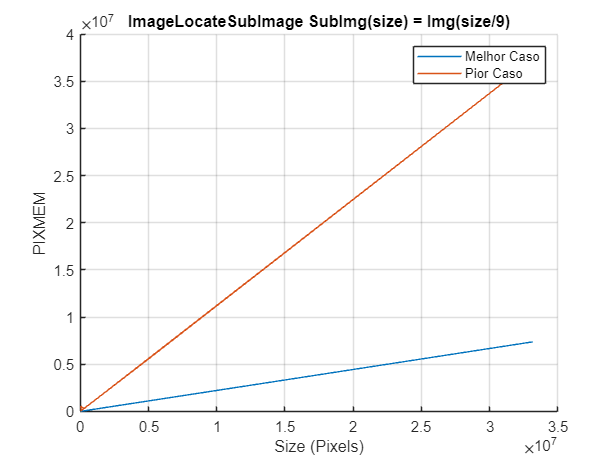

best_locate = fopen('best_locate.txt', 'r');

if best_locate == -1
    error('File cannot be opened');
end

fgetl(best_locate);  % Skip the first line
dataArray = textscan(best_locate, '%f %f', 'Delimiter', ' ', 'MultipleDelimsAsOne', true);
fclose(best_locate);

% Extracting columns
pixmemColumn = dataArray{1};  % First column
timeColumn = dataArray{2};   % Second column

%%%%%%%%%%%%%%%%%%%%%%%%% SIZE    %%%%%%%%%%%%%%%%%

sizeFile = fopen('sizes.txt','r');
if sizeFile == -1
    error('File cannot be opened');
end
fgetl(sizeFile);  % Skip the first line
dataArraySize = textscan(sizeFile, '%f','Delimiter', ' ', 'MultipleDelimsAsOne', true);
fclose(sizeFile);
sizeColumn = dataArraySize{1};  % Size data

%%%%%%%%%%%%%%%%%%%%% BAD BLURRRRRRR %%%%%%%%%%%

worst_locate = fopen('worst_locate.txt', 'r');

if worst_locate == -1
    error('File cannot be opened');
end

fgetl(worst_locate);  % Skip the first line
dataArrayBad = textscan(worst_locate, '%f %f %f', 'Delimiter', ' ', 'MultipleDelimsAsOne', true);
fclose(worst_locate);

% Extracting columns
pixmemColumnBad = dataArrayBad{1};  % First column
timeColumnBad = dataArrayBad{2};   % Second column

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PLOT %%%%%%%%%
hold on;
grid on;
title("ImageLocateSubImage SubImg(size) = Img(size/9)");
xlabel("Size (Pixels)");
ylabel("PIXMEM");

plot(sizeColumn, pixmemColumn);
plot(sizeColumn, pixmemColumnBad);
legend('Melhor Caso', 'Pior Caso');  % Legenda após todas as plotagens

saveas(gcf, 'locate_sub.png');